# Example FSM2DTTI solver

## Introduction

FSM2DTTI code estimates first-arrival traveltimes for quasi-P waves in anisotropic medium. 

See details of the method in: 

Waheed, U. B., Yarman, C. E., & Flagg, G. (2015). An iterative,  fast-sweeping-based eikonal solver for 3D tilted anisotropic media. *Geophysics*, *80*(3), C49-

[https://library.seg.org/doi/abs/10.1190/geo2014-0375.1](https://library.seg.org/doi/abs/10.1190/geo2014-0375.1)

## Define MLIB folder

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Define grid and velocity model

Create Grid file

For 2D codes only "x" and "z" fields are important

G=GridClass;

%    [m]        [m]       [m]          [s]
G.x0=0;      G.y0=0;    G.z0=0;      G.t0 = 0.00;            % initial point
G.nx=1001;   G.ny=1;    G.nz=501;    G.nt = 300;             % grid size
G.dx=1;      G.dy=0;    G.dz=1;      G.dt = 0.001;           % grid step (meter)

G.gridInfo;

Information about grid:
x0=0, dx=1, Nx=1001.
y0=0, dy=0, Ny=1.
z0=0, dz=1, Nz=501.
t0=0, dt=0.001, Nt=300.


G.setGrid;

## Define source position S = [Sx, Sy, Sz]

For 2D code only Sx and Sz are important

S = [100, 0, 0];

## Define velocity model

Velocity model includes:

- Vp - vertical velocity of P wave, matrix of size [G.nx G.nz]

- Epsilon - Thomsen parameter Epsilon, matrix of size [G.nx G.nz]

- Delta - Thomsen parameter Delta, matrix of size [G.nx G.nz]

- Theta - tilt of the symmetry axis (degree), matrix of size [G.nx G.nz]

NB! Theta = 0 for VTI medium

Vp      = 4500*ones(G.nx,G.nz)+ 2*ones(G.nx,1)*G.zz; 
Epsilon =  0.2*ones(G.nx,G.nz);
Delta   =-0.15*ones(G.nx,G.nz);
Theta   =   30*ones(G.nx,G.nz);

## Plot velocity model

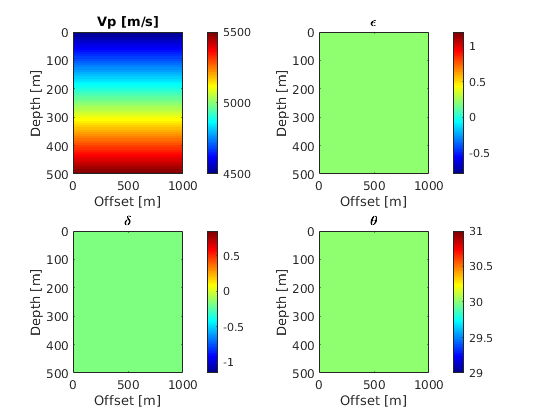

figure(1)
subplot(2,2,1)
imagesc(G.xx, G.zz, Vp'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('Vp [m/s]')

subplot(2,2,2)
imagesc(G.xx, G.zz, Epsilon'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\epsilon')

subplot(2,2,3)
imagesc(G.xx, G.zz, Delta'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\delta')

subplot(2,2,4)
imagesc(G.xx, G.zz, Theta'); 
colormap('jet')
colorbar;
xlabel('Offset [m]');
ylabel('Depth [m]');
title('\theta')

## Compile the code

(required just once)

mex FSM2DTTI.cpp

## Compute traveltimes with FSM2DTTI code

tic
tti  = FSM2DTTI(G, S, Vp, Epsilon, Delta, Theta);

Elapsed time is 3.096868 seconds.


toc

## Plot traveltimes and wavefronts

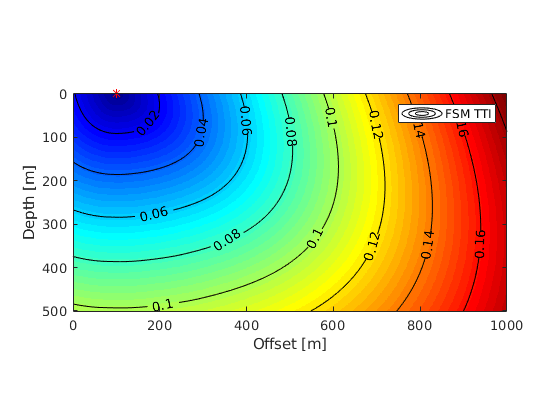

figure(2)
imagesc(G.xx, G.zz, tti'); 
colormap('jet')
hold on 
contour(G.xx, G.zz, tti', 'ShowText', 'on', 'Color', 'black')
xlabel('Offset [m]');
ylabel('Depth [m]');
set(gca, 'YDir', 'reverse');
axis([G.x0,G.mx,G.z0,G.mz])
plot(S(1), S(3), '*r'); 
legend('FSM TTI');
axis equal;